# Intoduction to Matched Filter and Kalman Filter

#### Objective

In this MATLAB script, we will be introduced to the concepts of Matched filter and Kalman filter with an example each.

#### Matched Filter 

The matched filter is a linear filter that maximizes Signal-to-Noise ratio 

The working of a matched filter in signal processing is done by comparing a recognized template or delayed signal with an unidentified signal to notice the existence of the template within the unknown signal. 

For a deterministic signal in white Gaussian noise, you can maximize the SNR at the receiver by using a filter matched to the signal. The matched filter is a time-reversed and conjugated version of the signal.

#### Matched Filter Example

- Install Phased Array System Toolbox on MATLAB

- The `LinearFMWaveform` object creates a linear FM pulse waveform.

waveform = phased.LinearFMWaveform('PulseWidth',1e-4,'PRF',5e3);

- Create the signal using the above object

x = waveform();

- Create a matched filter system object. 

- Using the object perform matched filtering on the input waveform

filter = phased.MatchedFilter( ...
    'Coefficients',getMatchedFilter(waveform));
y = filter(x);

- Plot the input signal and the matched filter output

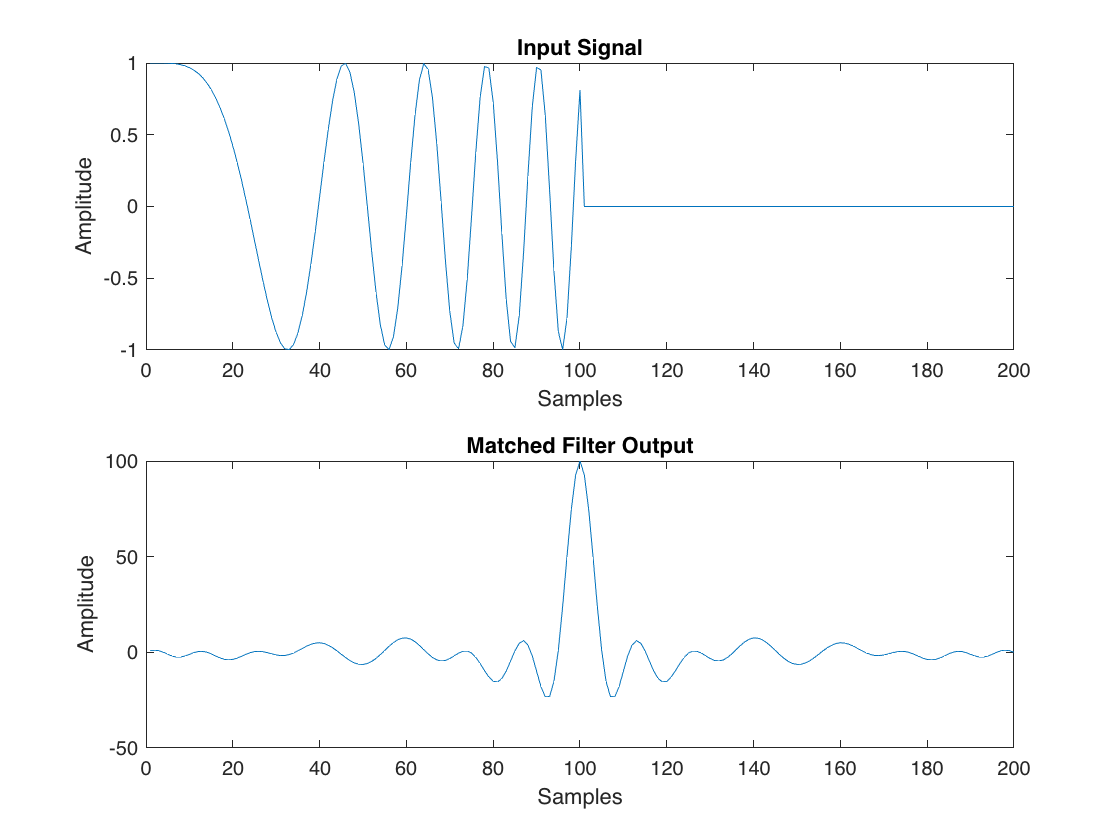

subplot(2,1,1),plot(real(x))
xlabel('Samples')
ylabel('Amplitude')
title('Input Signal')
subplot(2,1,2),plot(real(y))
xlabel('Samples')
ylabel('Amplitude')

title('Matched Filter Output')

#### Kalman Filter 

A Kalman filter is a recursive algorithm for estimating the evolving state of a process when measurements are made on the process. The filter assumes the state-space model, including the state model and the measurement model, is linear. When the process noise and measurement noise are Gaussian and the motion model is linear, the Kalman filter is optimal. 

#### Kalman Filter Example

A `trackingKF` object is a discrete-time linear Kalman filter used to track states, such as positions and velocities of target platforms.

- Install Sensor Fusion and Tracking Toolbox on MATLAB

- Assume an object is located in xy-space and specify values for x and y

- Specify the initial state estimate to have zero velocity.

x = 5.3;
y = 3.6;
initialState = [x;0;y;0];

- Create a linear Kalman filter that uses a 2D constant velocity motion model with the created initial state.

KF = trackingKF('MotionModel','2D Constant Velocity','State',initialState);

- Create measured positions for the object on a constant-velocity trajectory.

vx = 0.2;
vy = 0.1;
T  = 0.5;
pos = [0:vx*T:2;
       5:vy*T:6]';

- Predict and correct the state of the object

for k = 1:size(pos,1)
    pstates(k,:) = predict(KF,T);
    cstates(k,:) = correct(KF,pos(k,:));
end

- Plot the tracks

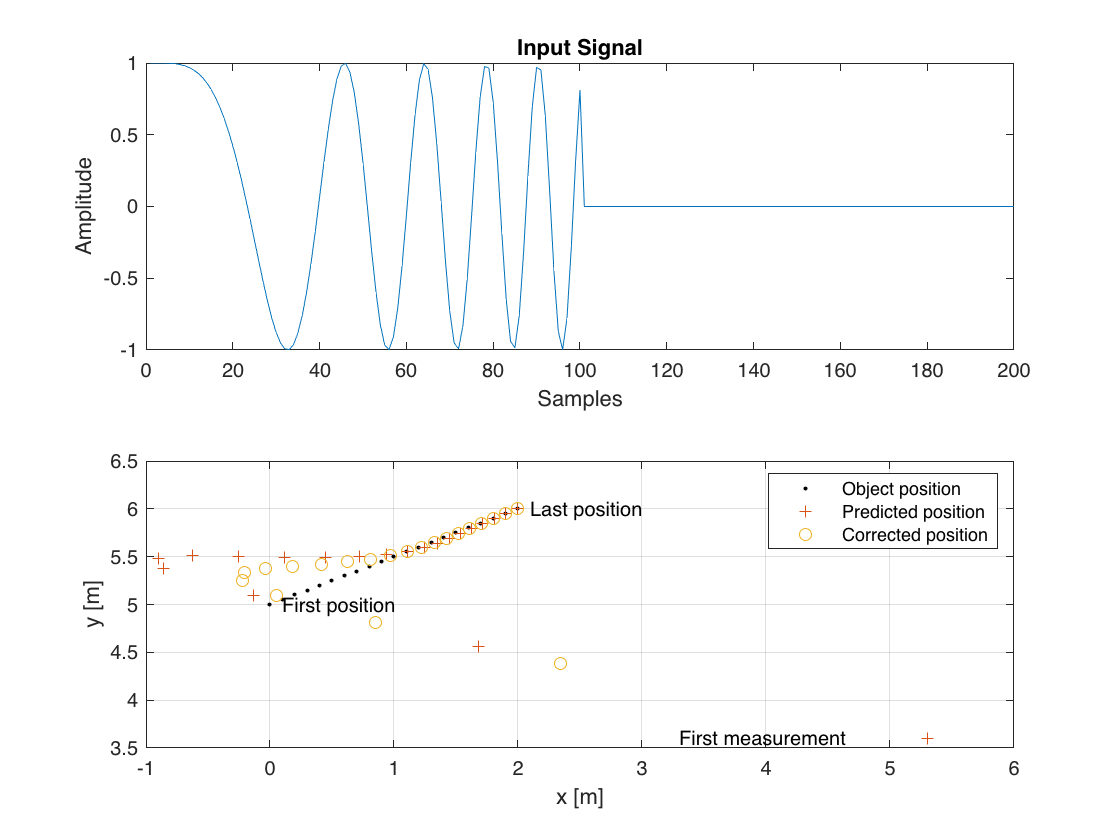

plot(pos(:,1),pos(:,2),"k.",pstates(:,1),pstates(:,3),"+", ...
    cstates(:,1),cstates(:,3),"o")
xlabel("x [m]")
ylabel("y [m]")
grid
xt  = [x-2, pos(1,1)+0.1, pos(end,1)+0.1];
yt = [y, pos(1,2), pos(end,2)];

text(xt,yt,["First measurement","First position","Last position"])
legend("Object position","Predicted position","Corrected position")